%Constants

m = 1; %Kg
l = 2;
ratio = 0.5;
d = ratio*l;
g = 9.8;
h = 0.01; %Time step



%Iteration - 1 without Linearization
syms theta omega;

init_t = 0;
final_t = 5;
time = init_t:h:final_t;

q_init = [60*pi/180;0];
q_iters = zeros([2 size(time,2)]);
q_iters(:,1) = q_init;

F = [omega;(-3/4)*g*sin(theta)/d];
i = 1;

digits(10);
for t = init_t:h:final_t-h
    q_iters(:,i+1) = q_iters(:,i) + (h*vpa(subs(F,[theta,omega],transpose(q_iters(:,i)))));
    i = i+1;
end


%Iteration-2 after linearizing
 
syms theta omega;

init_t = 0;
final_t = 5;
time = init_t:h:final_t;

q_init = [60*pi/180;0];
q_iters = zeros([2 size(time,2)]);
q_iters(:,1) = q_init;

F = [omega;(-3/4)*g*(theta)/d];
i = 1;

digits(10);
for t = init_t:h:final_t-h
    q_iters(:,i+1) = q_iters(:,i) + (h*vpa(subs(F,[theta,omega],transpose(q_iters(:,i)))));
    i = i+1;
end


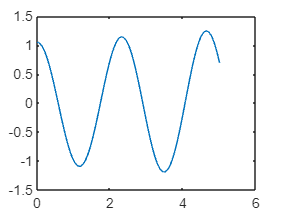


plot(time,q_iters(1,:))